## **Day 2 データの前処理**

**Ex.01~Ex.03を埋めてみましょう。**

### **★下準備**

筋電に由来する電位変動は5~500Hz付近に見られる。

なので、サンプリングレート(fs)はナイキスト周波数が500Hzになるようにすること。

参照：https://jp.mathworks.com/help/matlab/math/basic-spectral-analysis.html

%%clear all %%続けて

load('sample.mat');


Data=Dev3_1;%使用するデータの名前

fs=1000;%サンプル周波数




%%Dev3_X内のチャンネルの情報を取り出して、変数名をつけておく。
Ch1_emg=Data.Dev3_ai1; 
%Ch2=Data.Dev3_ai2;  %%ch2がある場合  


%その他変数の準備
dt=1/fs; 
n=length(Ch1_emg);
t=Data.Time;

ひとまず計測した前処理前の筋電図を可視化してみましょう

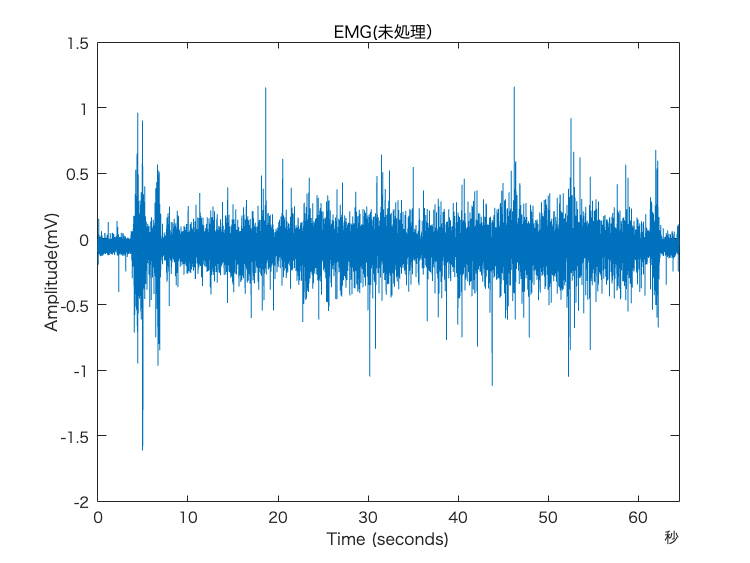

plot(t,Ch1_emg)
xlabel('Time (seconds)')
ylabel('Amplitude(V)')
xlim([0 t(end)])
title('EMG(未処理）')

### **★Frequency Domainの表示**

ここから周波数解析を行ったり、ノイズの影響をどのくらい受けているかを見るためにパワースペクトル密度を表示します。

ピリオドグラム法を用いて片側パワースペクトル密度を求めましょう。

`離散的にサンプリングされた時系列y(t)のFourier変換をY(k)とします(`各周波数が k 番目にサンプリングされていたという意味で，k の関数と表現)`。`

その時、パワー・スペクトル密度Syは以下の式で与えられます。


$$S\left(f_k \right)=\frac{1}{N}\left({Y\left(k\right)}^2 \right)$$


信号は実数値であり、$S(f_k)=S(-f_k)
$と，正負の周波数について同じ値を持つ．

ただし、周波数 0およびナイキスト周波数は重複しないため、

正の周波数のみを考慮した片側スペクトル密度は、


$$$k=\left\lbrace \begin{array}{ll}
1,..., \frac{n}{2}-1,      ~~~~~~~~ G(f_k)=\frac{2}{n}|Y(k)|^2 , \\
 0 ,  ~~~~~~~~~~~~~~ ~~~~ ~~~~~  G(0)= \frac{1}{n}|Y(0)|^2, \\
\frac{n}{2} , ~~~~~~~~~~~ ~~~~~~~ ~~~~~ G(f_{n/2})=\frac{1}{n}|Y(n/2)|^2\\
\end{array}\right.$$$


で表すことができます。

より詳細な説明は

[https://jp.mathworks.com/help/signal/ug/power-spectral-density-estimates-using-fft.html](https://jp.mathworks.com/help/signal/ug/power-spectral-density-estimates-using-fft.html)

https://www.sci.hokudai.ac.jp/~minobe/data_anal/chap3.pdf

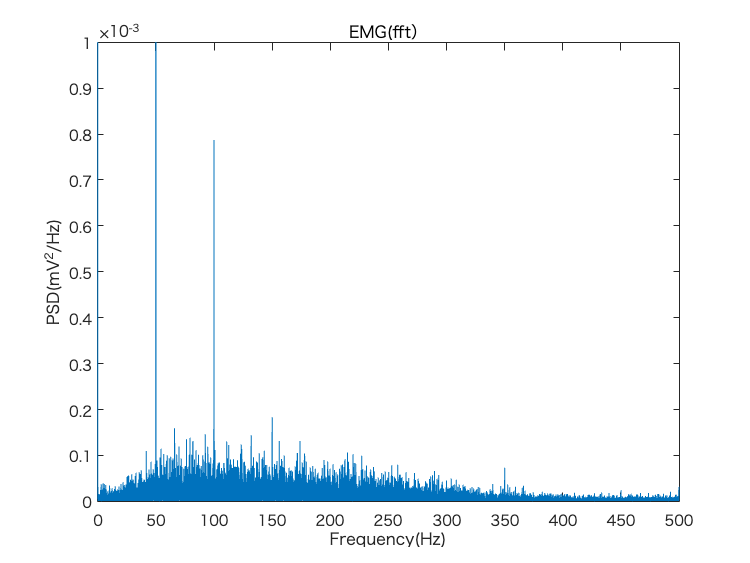

Ch1_fft= fft(Ch1_emg);

xdft = Ch1_fft(1:n/2+1);
psdx = (1/(fs*n)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);%
f1 = 0:fs/n:fs/2;

%%以下と（ほぼ）同義
%%%[psdx,f1] = periodogram(ch_1,rectwin(n),n,fs,'ConfidenceLevel',0.95);


plot(f1,psdx)
ylim([0 0.001])
xlabel('Frequency(Hz)')
ylabel('PSD(V^2/Hz)')
title('EMG(fft）')

パワースペクトル密度を表示しています。

考察ポイント：パワースペクトル密度を使うメリットは？

### **★ノイズの除去**

50Hz や100Hzのあたりにスパイクが発生していますが、これは電源ノイズなどによる影響です。これを取り除いて、正確なデータ解析が行えるようにしましょう。東京では電源ノイズは50Hzです。まずはこれをバンドストップフィルタで処理しましょう。除去する範囲は49~51Hz, フィルタのタイプはButterworth filterを選択します。

フィルタ特性を見たい場合はfvtoolを利用してください。https://jp.mathworks.com/help/signal/ref/fvtool.html

d = designfilt('bandstopiir','FilterOrder',2, ...
               'HalfPowerFrequency1',49,'HalfPowerFrequency2',51, ...
               'DesignMethod','butter','SampleRate',fs);

Ch1_denoise = filter(d,Ch1_emg);

電源ノイズが処理できているか、確認します。

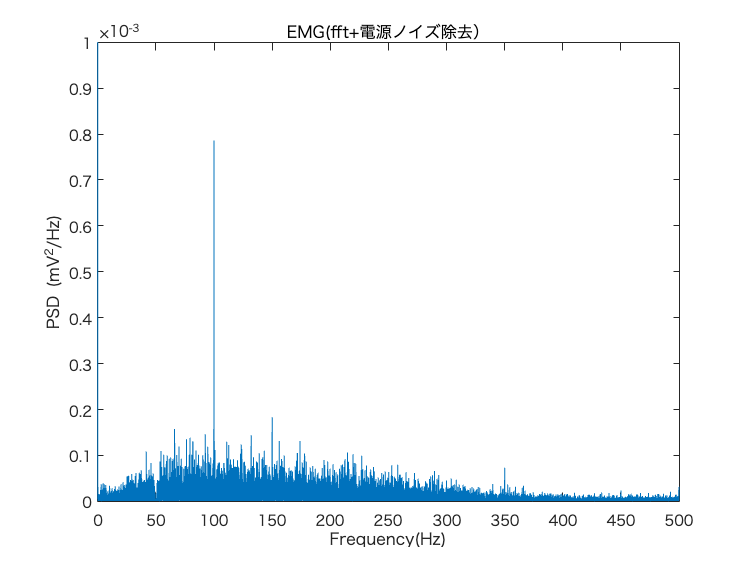

[Ch1_denoise_pr,f1] = periodogram(Ch1_denoise,rectwin(n),n,fs,'ConfidenceLevel',0.95);

plot(f1, Ch1_denoise_pr)
ylim([0 0.001])
xlabel('Frequency(Hz)')
ylabel('PSD (V^2/Hz)')
title('EMG(fft+電源ノイズ除去）')

**★高調波ノイズの除去**

100Hz 以降、50Hz毎に立ち上がるスパイクは、高調波電流の影響です。現代ではほとんどの電化製品から、高調波電流が発生しています（整流回路を持つインバータ、電源の交直変換 etc.）。基本周波数（東京では50Hz）の 2~40倍の周波数波形が現れます。上の電源ノイズの除去を行ったフィルタを参考に、この高調波を除去しましょう。

#### **Ex. 01: 高調波の除去**





%%Ch1_denoise=
%%最終出力をCh1_denoiseにしてください。

正しく除去できているか確認しましょう。

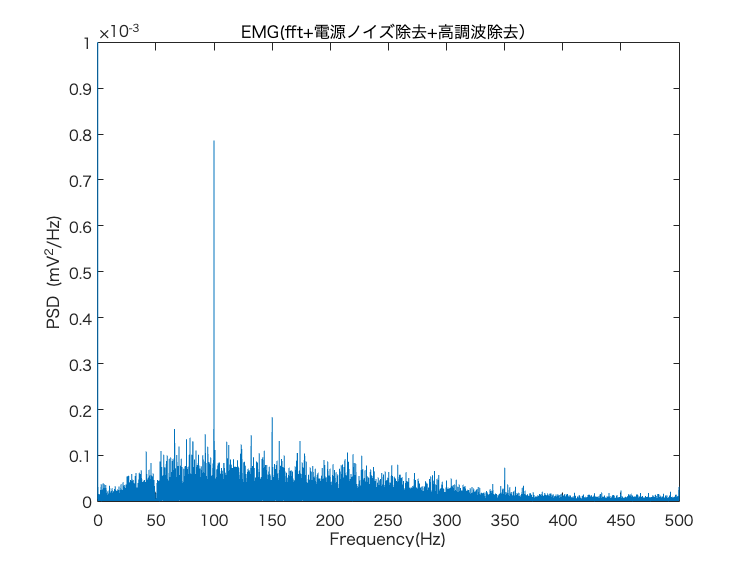


[Ch1_denoise_pr,f1] = periodogram(Ch1_denoise,rectwin(n),n,fs,'ConfidenceLevel',0.95);

plot(f1, Ch1_denoise_pr)
ylim([0 0.001])
xlabel('Frequency(Hz)')
ylabel('PSD (V^2/Hz)')
title('EMG(fft+電源ノイズ除去+高調波除去）')

-->Day2 part2へ続く(clear allなどをしないように！！）